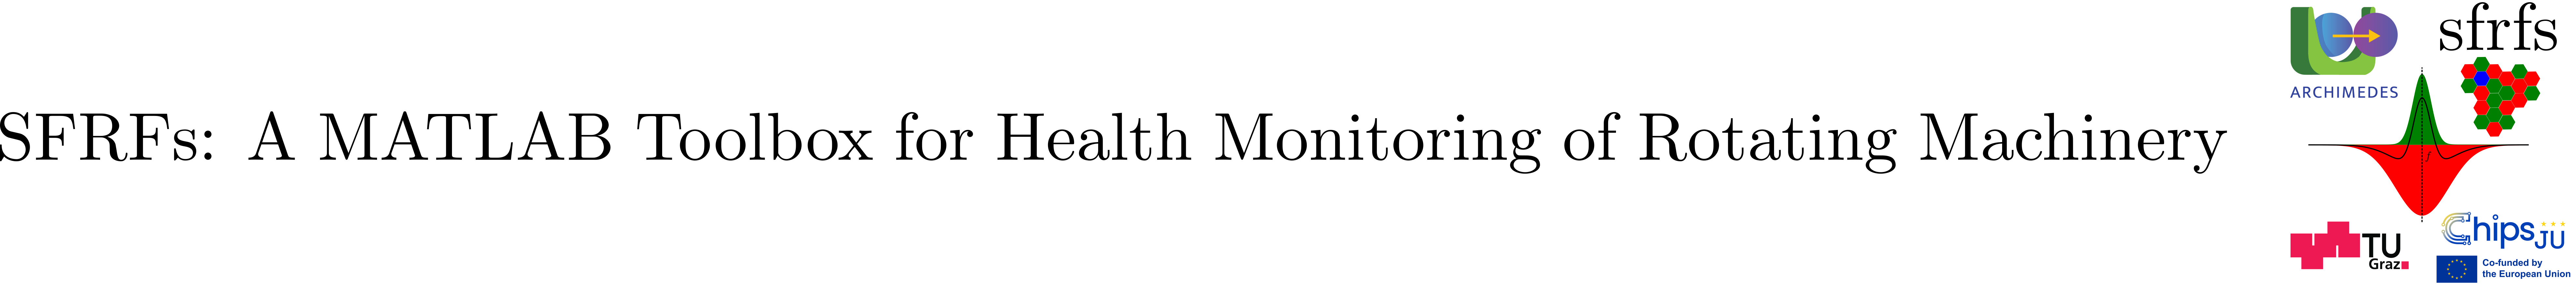

# ContrastPolarityDegradationExplorer

**(Explores stored contrast-polarity representations across bearing runs)**

## **Summary**

ContrastPolarityDegradationExplorer is a handle class that provides an interactive interface for examining stored contrast-polarity representations across bearing runs and monitored fault-frequency families. It supports the exploration of observable channels, epistemic support, polarity events, harmonic relevance, and temporal polarity behavior without recomputing the underlying contrast-polarity representations.

**Key features:**

- Provides an interactive interface for exploring previously computed contrast-polarity datasets.

- Supports selection of individual bearing runs and monitored fault-frequency families.

- Displays temporal observables and harmonic-level representations, including optional polarity-event overlays.

- Provides complementary views of epistemic support, event density, polarity balance, harmonic polarity trajectories, and harmonic relevance.

- Supports configurable snapshot windows and robust percentile-based display scaling.

- Provides harmonic relevance summaries based on accumulated absolute responses or event occurrences.

- Displays operating-condition metadata, representation dimensions, and available bearing failure annotations.

- Supports optional bearing and receptive-field parameters for harmonic-frequency interpretation.

- Operates on stored representations without recomputing spectral fault receptive fields or contrast-polarity channels.

- Retains an exploratory interpretation without prescribing diagnostic or prognostic conclusions.

## Description

`ContrastPolarityDegradationExplorer` provides an interactive interface for examining contrast-polarity representations previously constructed from bearing observations. It operates on the canonical exploration dataset generated by `ContrastPolarityExplorationDatasetBuilder`, preserving the separation between representation construction and subsequent exploratory analysis.

The explorer accepts a MATLAB table containing bearing-run metadata, monitored fault-frequency families, sensor-local contrasts, resolved contrasts, temporal polarity events, and conventional condition indicators. Each table row represents one bearing run and one monitored fault-frequency family. Matrix-valued channels preserve their observation-by-harmonic dimensions.

The graphical interface supports six complementary views:

- **DirectObservable.** Displays selected temporal or harmonic-level observables, with optional overlays of stored polarity events.

- **EpistemicSupport.** Displays the number of supported and censored harmonic channels at each observation, using nonzero resolved contrast as the operational support criterion.

- **EventDensity.** Counts occurrences of a selected polarity-event type across harmonic channels for each observation.

- **PolarityBalance.** Displays the numbers of positive, negative, and zero-valued resolved contrasts across harmonic channels.

- **HarmonicPolarityTrajectory.** Represents the temporal trajectory of positive and negative contrast magnitudes aggregated across harmonic channels at each observation.

- **HarmonicRelevance.** Computes accumulated absolute responses or event counts for individual harmonics, supporting configurable cumulative relevance retention and relative importance indices.

The interface allows users to select bearing runs and fault-frequency families, restrict the displayed observation window, and adjust display scaling. Available operating-condition metadata, channel dimensions, and external failure annotations are presented alongside the selected representation. Optional bearing and receptive-field parameters support the interpretation of harmonic indices in terms of characteristic frequencies.

The explorer operates exclusively on previously constructed contrast-polarity channels. Although it computes descriptive summaries and transformations for display, it does not reconstruct spectral fault receptive fields, recompute sensor-local contrasts or agreement filters, or regenerate polarity-event channels.

Exploration here refers to the examination and descriptive characterization of stored representations. The class does not independently infer bearing degradation states, perform fault diagnosis, estimate remaining useful life, or establish prognostic conclusions.

See also: [`ContrastPolarityExplorationDatasetBuilder`](matlab:open('./ContrastPolarityExplorationDatasetBuilder.mlx')), [`ContrastPolarityChannelDatasetBuilder`](matlab:open('./ContrastPolarityChannelDatasetBuilder.mlx')), [`LiftedHarmonicGainFunctions`](matlab:open('./LiftedHarmonicGainFunctions.mlx')), [`SFRFsParametersRollingBearings`](matlab:open('./SFRFsParametersRollingBearings.mlx')).

### Public properties

`ContrastPolarityDegradationExplorer` exposes one publicly inspectable property. Its value is established during construction and cannot be reassigned through ordinary property assignment.

The property has private set access (`SetAccess ``= ``private`). The explorer retains the supplied dataset for subsequent selection and visualization.

The optional bearing and receptive-field parameters, graphical controls, and rendering state are maintained as private properties and are not exposed through the public interface.

### Constructor

The constructor initializes the explorer with a previously constructed contrast-polarity dataset and, optionally, the bearing geometry and spectral fault receptive-field parameters used in the experiment. It stores the supplied information for interactive exploration without recomputing the underlying representations.

#### Syntax

explorer = viz.ContrastPolarityDegradationExplorer( ...

    datasetTable = dataset)

explorer = viz.ContrastPolarityDegradationExplorer( ...

    datasetTable = dataset, ...

    bearingParameters = bp, ...

    sfrfsParameters = sfrfsParams)

#### Parameters

The `datasetTable` parameter is required. The remaining parameters are optional name-value arguments.

The constructor requires a nonempty dataset table. The expected representation schema is that produced by `ContrastPolarityExplorationDatasetBuilder`, including `Label`, `MonitoredFaultFamily`, and the channels required by the available visualization modes.

The optional parameters are retained for frequency-related visualization. They do not cause spectral fault receptive fields or contrast-polarity representations to be recomputed.

**Output**

`explorer: viz.ContrastPolarityDegradationExplorer` object.

A handle object that retains the supplied dataset and configuration and provides the `render` method for launching the interactive exploration interface. The graphical interface is not created during construction.

### render

The `render` method launches the interactive contrast-polarity explorer using the dataset and optional configuration supplied during construction.

The graphical interface provides controls for selecting a bearing run, monitored fault-frequency family, visualization mode, and observation window. It displays the selected representation alongside relevant metadata and descriptive information.

Rendering uses stored contrast-polarity representations and may compute descriptive quantities for display. It does not reconstruct receptive fields or regenerate the underlying dataset.

#### Syntax

explorer.render()

#### Parameters

`explorer` — `viz.ContrastPolarityDegradationExplorer` object.

A previously constructed explorer containing a nonempty canonical exploration dataset.

#### Output

The method does not return an output argument. It creates an interactive MATLAB figure containing a selection panel and a visualization area.

#### Interactive controls

#### Processing behavior

The method creates a graphical interface with a selection panel and a single visualization axis. Bearing and fault-family selections identify one row of the canonical dataset, while the selected view determines the descriptive transformation and graphical representation.

The available visualization modes operate on stored observation histories and preserve their temporal and harmonic indexing. Where applicable, the specified observation window restricts the displayed data without modifying the original dataset.

The information panel reports relevant metadata, representation dimensions, diagnostic annotations, or harmonic-relevance statistics according to the selected view.

The method does not modify the stored dataset or perform diagnosis, prognosis, or automatic hypothesis selection.

## Example

This example opens a file-selection dialog to retrieve a previously generated contrast-polarity exploration dataset, extracts the canonical table, and launches the interactive explorer. No dataset generation or contrast-polarity computation is performed.

### Select and load the exploration dataset

This example assumes that a contrast-polarity exploration dataset has already been generated and saved to a MAT-file. If no dataset is available, refer to the API documentation for [`ContrastPolarityExplorationDatasetBuilder`](matlab:open('./ContrastPolarityExplorationDatasetBuilder.mlx')), which provides the complete workflow for constructing and saving an exploration dataset from an ensemble of bearing observations.

% Select and load the exploration dataset

[file, path] = uigetfile( ...
    "*.mat", ...
    "Select a contrast-polarity exploration dataset");

if isequal(file, 0)
    error("Dataset selection cancelled.");
end

datasetFile = fullfile(path, file);

S = builtin("load", datasetFile, "channelRunsQ95");

assert(isfield(S, "channelRunsQ95"), ...
    "The selected MAT-file does not contain channelRunsQ95.");

dataset = S.channelRunsQ95;

fprintf("Loaded exploration dataset: %d rows, %d variables\n", ...
    height(dataset), width(dataset));

Loaded exploration dataset: 12 rows, 37 variables


### Construct and launch the explorer

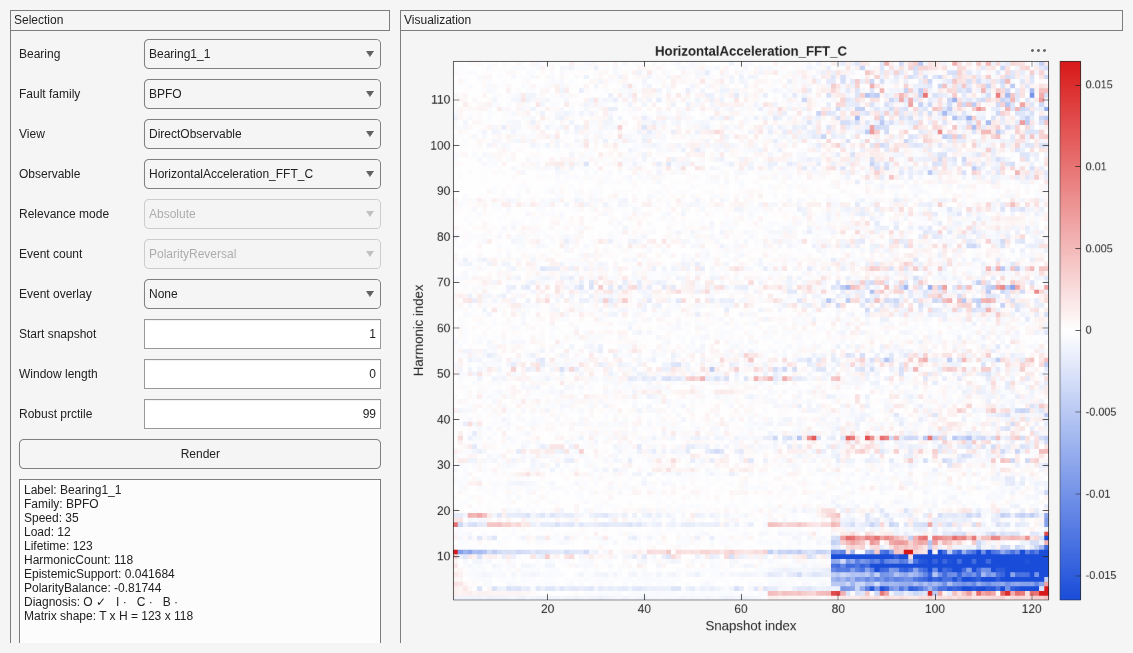

% Launch the contrast-polarity explorer

explorer = viz.ContrastPolarityDegradationExplorer( ...
    datasetTable = dataset);

explorer.render();

## API Documentation

The MATLAB documentation for `viz.ContrastPolarityDegradationExplorer` provides access to the class description, constructor, and public `render` method.

The following commands open the documentation directly from MATLAB.

help viz.ContrastPolarityDegradationExplorer

 ContrastPolarityDegradationExplorer Explore stored contrast-polarity representations.
 
  ContrastPolarityDegradationExplorer provides an interactive interface
  for examining the canonical exploration dataset produced by
  ContrastPolarityExplorationDatasetBuilder.
 
  The explorer operates on previously computed representations.
  It does not reconstruct spectral fault receptive fields, recompute
  contrast-polarity channels, or infer diagnostic or prognostic states.
 
  The interface supports selection by bearing and monitored fault
  family, snapshot-window navigation, and six complementary views:
 
    DirectObservable
    EpistemicSupport
    EventDensity
    PolarityBalance
    HarmonicPolarityTrajectory
    HarmonicRelevance
 
  Constructor:
 
    explorer = viz.ContrastPolarityDegradationExplorer( ...
        datasetTable = channelRunsQ95);
 
  Optional parameters:
 
    bearingParameters - Bearing geometry and frequency para

doc viz.ContrastPolarityDegradationExplorer

## Source Code

The MATLAB implementation of `viz.ContrastPolarityDegradationExplorer` can be inspected directly using the MATLAB Editor.

The following command opens the class source code.

edit viz.ContrastPolarityDegradationExplorer

## Testing

The integration of `viz.ContrastPolarityDegradationExplorer` was tested interactively using a previously generated XJTU-SY contrast-polarity exploration dataset.

The test verified successful dataset loading, explorer construction, graphical interface initialization, and interactive examination of stored representations. Bearing-run and fault-frequency-family selections, visualization modes, and associated information displays were exercised.

The diagnostic annotation display was also checked against the original XJTU-SY failure lookup, confirming that the explorer presents the available bearing failure annotations correctly.

The test did not regenerate spectral fault receptive fields or contrast-polarity channels. All visualizations were produced from previously computed and stored representations.

This constitutes an interactive integration test rather than an automated unit-test suite.

## How to Cite

If you use `ContrastPolarityDegradationExplorer` in your research, please cite the publications describing the Spectral Fault Receptive Fields methodology and its contrast-polarity extensions:

- Muñoz Gutiérrez, S., & Wotawa, F. (2025). Optimized Spectral Fault Receptive Fields for Diagnosis-Informed Prognosis. In *Proceedings of the 36th International Workshop on Principles of Diagnosis (DX 2025).* [https://doi.org/10.4230/OASIcs.DX.2025.9](https://doi.org/10.4230/OASIcs.DX.2025.9)

- Muñoz Gutiérrez, S., & Wotawa, F. (2026). Spectral Contrast Polarity Analysis and Adaptive Sensor Fusion for Bearing Degradation Monitoring. In *Proceedings of the 2026 13th International Conference on Dependable Systems and Their Applications (DSA 2026).* IEEE Conference Publishing Services (CPS).

For the XJTU-SY bearing dataset, please also cite Wang et al. (2020), as listed in the References section.

## References

- [1] Muñoz Gutiérrez, S., & Wotawa, F. (2025). Optimized Spectral Fault Receptive Fields for Diagnosis-Informed Prognosis. In *Proceedings of the 36th International Conference on Principles of Diagnosis and Resilient Systems (DX 2025)*, OASIcs, Vol. 136, pp. 9:1–9:20. Schloss Dagstuhl – Leibniz-Zentrum für Informatik. [https://doi.org/10.4230/OASIcs.DX.2025.9](https://doi.org/10.4230/OASIcs.DX.2025.9)

- [2] Muñoz Gutiérrez, S., & Wotawa, F. (2025). A Practical Guide to Spectral Fault Receptive Fields: Parameterization and Usage in the SFRFs MATLAB Toolbox. Technical Report TR-SFRFs-v1.0.1. Zenodo.

- [3] Muñoz Gutiérrez, S., & Wotawa, F. (2026). Spectral Contrast Polarity Analysis and Adaptive Sensor Fusion for Bearing Degradation Monitoring. In *Proceedings of the 2026 13th International Conference on Dependable Systems and Their Applications (DSA 2026).* IEEE Conference Publishing Services (CPS).

- [4] Wang, B., Lei, Y., Li, N., & Li, N. (2020). A Hybrid Prognostics Approach for Estimating Remaining Useful Life of Rolling Element Bearings. *IEEE Transactions on Reliability, 69*(1), 401–412. [https://doi.org/10.1109/TR.2018.2882682](https://doi.org/10.1109/TR.2018.2882682)